%%IMAGE CLASSIFICATION  WITH GOOGLENET

eranko_ibile = imageDatastore('Animal_images', ...
'IncludeSubfolders',true, ...
'LabelSource','foldernames');

[imdsTrain,imdsValidation] = splitEachLabel(eranko_ibile,0.7,'randomized');

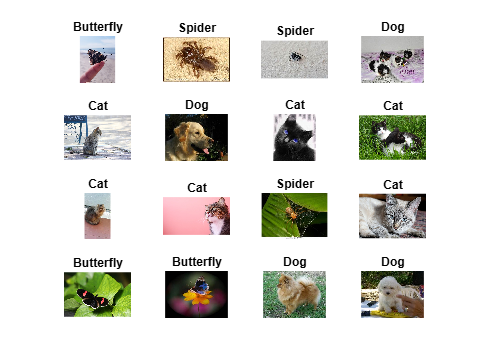


numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
subplot(4,4,i)
I = readimage(imdsTrain,idx(i));
imshow(I)
title(char(imdsTrain.Labels(idx(i))));
end

% Load GoogLeNet
net = googlenet;

%Resize images for GoogLeNet (224x224 input)
inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2), imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize(1:2), imdsValidation);

%  Replace final layers to match your animal classes
numClasses = numel(categories(imdsTrain.Labels));
lgraph = layerGraph(net);

% Create new final layers
newLayers = [
    fullyConnectedLayer(numClasses, 'Name', 'new_fc', ...
        'WeightLearnRateFactor', 20, 'BiasLearnRateFactor', 20)
    softmaxLayer('Name', 'new_softmax')
    classificationLayer('Name', 'new_output')];

% Replace layers
lgraph = replaceLayer(lgraph, 'loss3-classifier', newLayers(1));
lgraph = replaceLayer(lgraph, 'prob', newLayers(2));
lgraph = replaceLayer(lgraph, 'output', newLayers(3));

% Set training options
options = trainingOptions('sgdm', ...
    'MiniBatchSize', 32, ...
    'MaxEpochs', 6, ...
    'InitialLearnRate', 1e-4, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 10, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

% Train the model
netTransfer = trainNetwork(augimdsTrain, lgraph, options);

Unrecognized function or variable 'augimdsTrain'.

% Evaluate model on validation set
YPred = classify(netTransfer, augimdsValidation);
YValidation = imdsValidation.Labels;

accuracy = mean(YPred == YValidation);
disp(['Test Accuracy: ', num2str(accuracy * 100), '%']);

Test Accuracy: 97.7169%


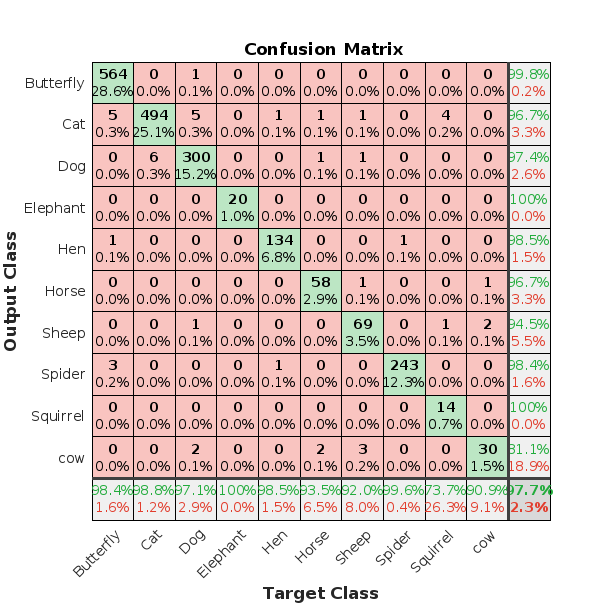

% Confusion Matrix 
plotconfusion(YValidation,YPred)